# Get and Set ROS 2 Parameters in Simulink

This example shows how to use ROS 2 parameters in Simulink® and share data over the ROS 2 network.

## Create and Get ROS 2 Parameter

Open the model.

modelName = "GetAndSetROS2Parameters";
open_system(modelName)

This model uses the Get Parameter block to create a parameter `myparam`. The parameter is associated with the ROS 2 node that the Simulink model creates during simulation. You can specify the initial value of `myparam` in the block parameters for the Get Parameter block.

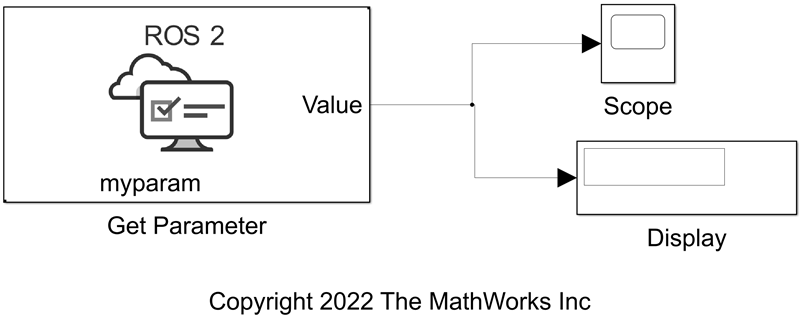

## Get and Set ROS 2 Parameter

To set the parameter associated with the Simulink model during the simulation, you must use programmatic commands to run simulation. Start the simulation.  

set_param(modelName,"SimulationCommand","start")

Pause the simulation to obtain the name of the ROS 2 node created by the Simulink model. Create a [`ros2param`](docid:ros_ref#mw_ab31a934-edcb-4950-8e37-1100cfb953ef) object for the node, to access its parameters.

set_param(modelName,"SimulationCommand","pause")

if get_param(modelName,"SimulationStatus") ~= "initializing"
    nodelist = ros2("node","list");
    simNodeIdx = strfind(nodelist,modelName);
    simNodeName = nodelist{1};
    paramObj = ros2param(simNodeName);
end

Continue the simulation. While the simulation is running, get the current value of the parameter by using the `get` object function on `ros2param` object. Then, set the new value of the parameter using the `set` object function. Observe the Scope to see that the value increases by 1 every simulation time step. Stop the simulation after `200` iterations.

set_param(modelName,"SimulationCommand","continue")
t = 0;
while get_param(modelName,"SimulationStatus") == "running"
    % Get and set parameter 
    [currParam,status] = get(paramObj,"myparam");
    if status
        set(paramObj,"myparam",currParam+1);
    end
    
    % Stop simulation after 200 iterations
    if t < 200
        t = t + 1;
    else
        set_param(modelName,"SimulationCommand","stop")
    end
end

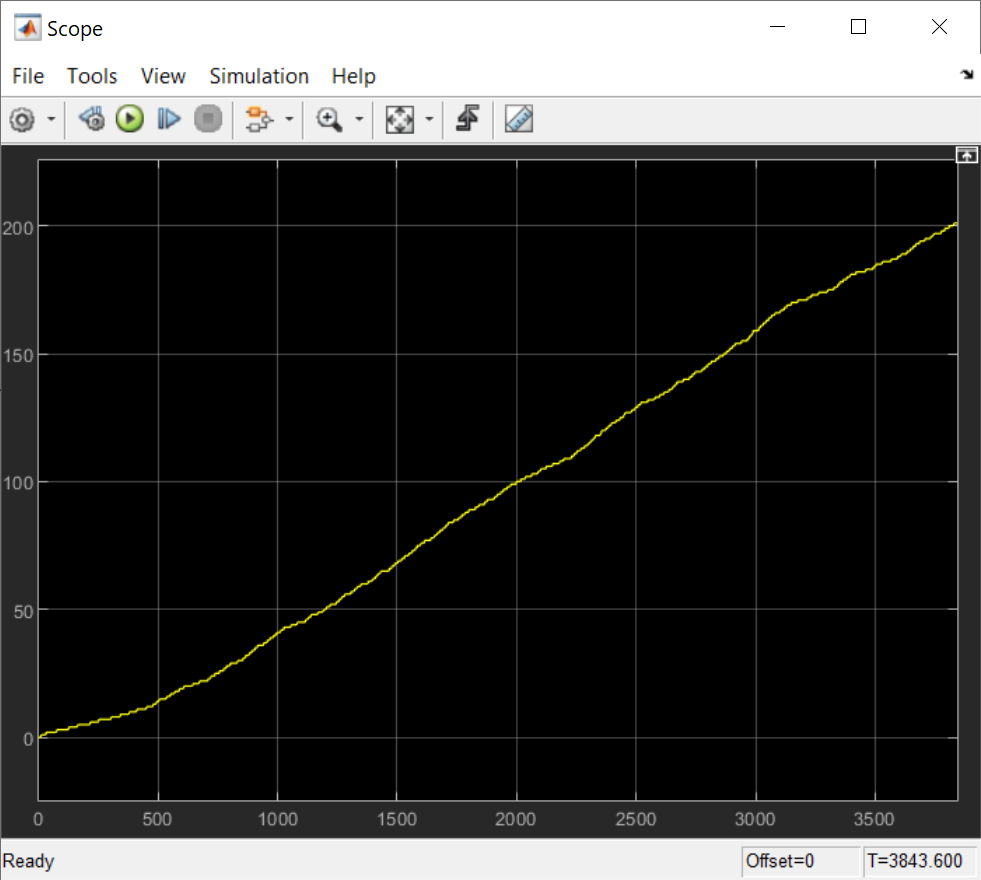

*Copyright 2022 The MathWorks, Inc.*